clear
proj = currentProject;
run('Mat_Prop.m');      % Import the material properties

# **Import Geometry from text file**

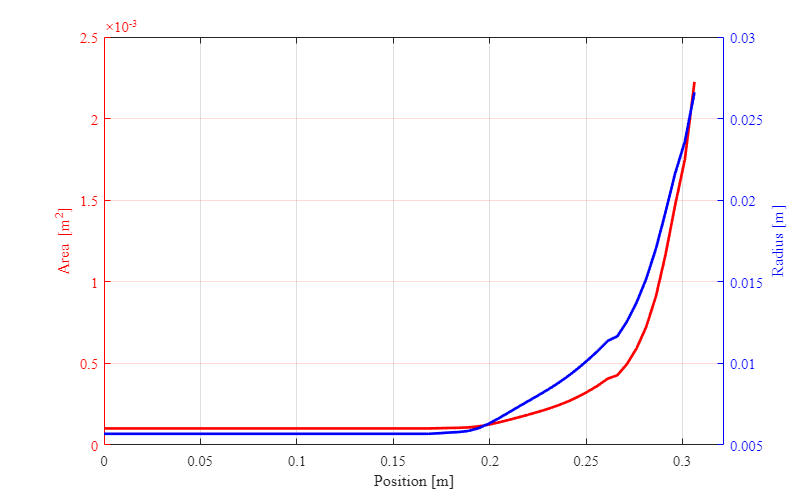

opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [3, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["Location", "Area"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
Geom_Horn = readtable("Geom_Horn.txt", opts);
clear opts

% Create plot of Geom_Horn.Location and Geom_Horn.Area
plotgeom(Geom_Horn.Location,Geom_Horn.Area);

# **Acoustical components**

## Horn

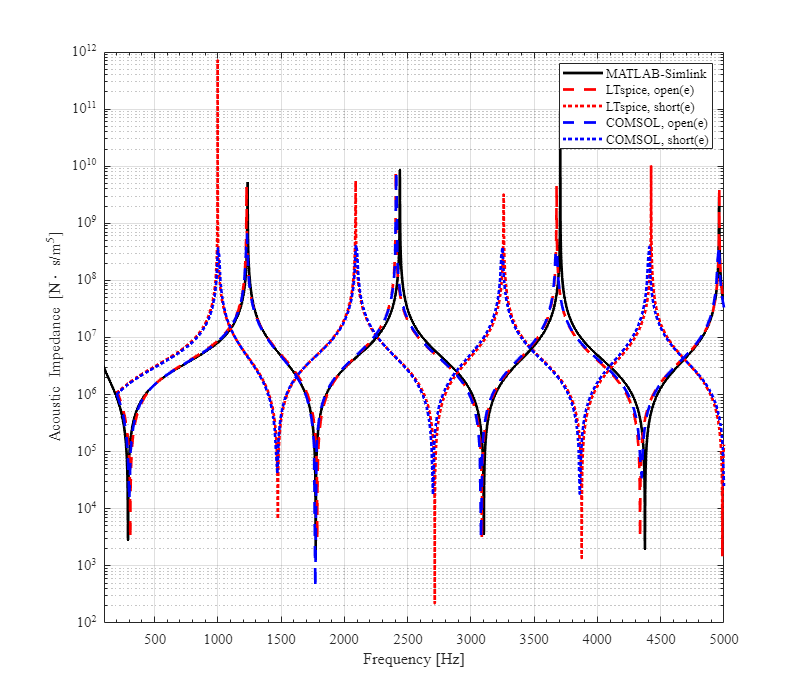

ac.ho.x     = Geom_Horn.Location(3:end)-Geom_Horn.Location(2:end-1);
                                                    % Length of subsection
ac.ho.s     = Geom_Horn.Area(3:end);                % Area of subsection
ac.ho.n     = size(ac.ho.x);                        % No. of subsection

ac.ho.L     = air.rho0./ac.ho.s.*ac.ho.x/2;         % L in T network of subsection
ac.ho.C     = ac.ho.s/(air.rho0*air.c^2).*ac.ho.x;  % C in T network of subsection

%% Specify the model name
ac.ho.model = 'AC_Horn';

%% Specify the analysis I/Os
% Get the analysis I/Os from the model
ac.ho.io = getlinio(ac.ho.model);

%% Specify the operating point
% Use the model initial condition
ac.ho.op = operpoint(ac.ho.model);

%% Linearize the model
ac.ho.sys = linearize(ac.ho.model,ac.ho.io,ac.ho.op);

w = linspace(0,2*pi*5000,5001);
freq = w/(2*pi);
[ac.ho.mag, ac.ho.phase] = bode(ac.ho.sys,w);

ac.ho.Z = squeeze(ac.ho.mag)';
ac.ho.argZ = squeeze(ac.ho.phase)';

ac.ho.LTspice = readLTspiceZ('AC -220722 - Horn_.txt',1,4801);
ac.ho.COMSOL.open   = readCOMSOLZ('AC -220722 - Horn, 2DX, open(e), abs(Z).txt',9);
ac.ho.COMSOL.short  = readCOMSOLZ('AC -220722 - Horn, 2DX, short(e), abs(Z).txt',9);

plotcompZ(freq,ac.ho.Z,...
    [ac.ho.LTspice.freq ac.ho.LTspice.freq],[ac.ho.LTspice.abs_z_o ac.ho.LTspice.abs_z_s],...
    [ac.ho.COMSOL.open.freq ac.ho.COMSOL.short.freq], [ac.ho.COMSOL.open.value ac.ho.COMSOL.short.value],...
    1e2,5e3,'linear');

## Parallel section

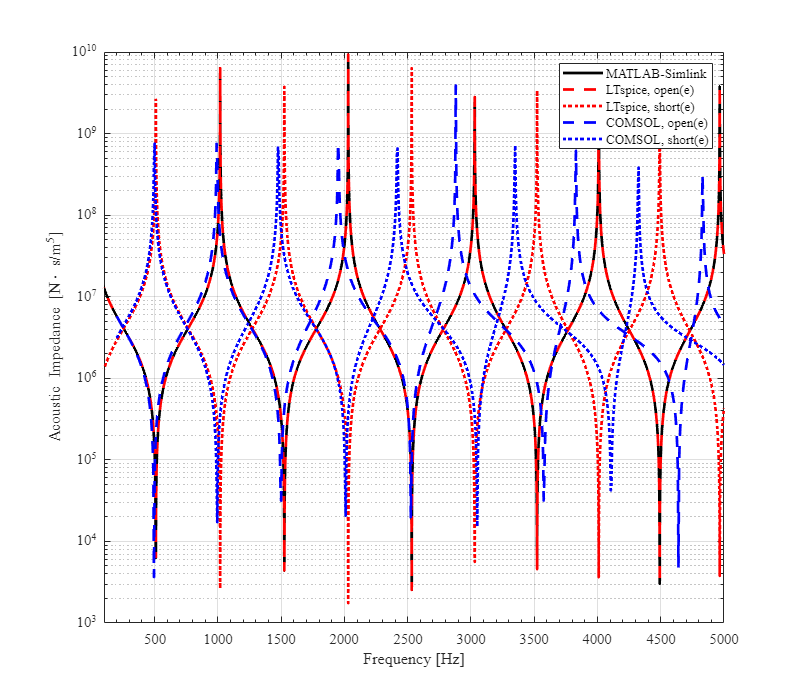

ac.ps.x     = Geom_Horn.Location(2);                % Length
ac.ps.s     = Geom_Horn.Area(2);                    % Area
ac.ps.n     = 20;                                   % No. of subsection

ac.ps.L     = air.rho0/ac.ps.s*(ac.ps.x/ac.ps.n);   % L in T network of subsection
ac.ps.C     = ac.ps.s/(air.rho0*air.c^2)*(ac.ps.x/ac.ps.n);
                                                    % C in T network of subsection

%% Specify the model name
ac.ps.model = 'AC_Parallel_Section';

%% Specify the analysis I/Os
% Get the analysis I/Os from the model
ac.ps.io = getlinio(ac.ps.model);

%% Specify the operating point
% Use the model initial condition
ac.ps.op = operpoint(ac.ps.model);

%% Linearize the model
ac.ps.sys = linearize(ac.ps.model,ac.ps.io,ac.ps.op);

w = linspace(0,2*pi*5000,5001);
freq = w/(2*pi);
[ac.ps.mag, ac.ps.phase] = bode(ac.ps.sys,w);

ac.ps.Z = squeeze(ac.ps.mag)';
ac.ps.argZ = squeeze(ac.ps.phase)';

ac.ps.LTspice = readLTspiceZ('AC -220722 - Parallel Section_.txt',1,5000);

ac.ps.COMSOL.open   = readCOMSOLZ('AC -220722 - Parallel Section, 2DX, open(e), abs(Z).txt',9);
ac.ps.COMSOL.short  = readCOMSOLZ('AC -220722 - Parallel Section, 2DX, short(e), abs(Z).txt',9);

plotcompZ(freq,ac.ps.Z,...
    [ac.ps.LTspice.freq ac.ps.LTspice.freq],[ac.ps.LTspice.abs_z_o ac.ps.LTspice.abs_z_s],...
    [ac.ps.COMSOL.open.freq ac.ps.COMSOL.short.freq], [ac.ps.COMSOL.open.value ac.ps.COMSOL.short.value],...
    1e2,5e3,'linear');

## Compressor (value from COMSOL Multiphysics)

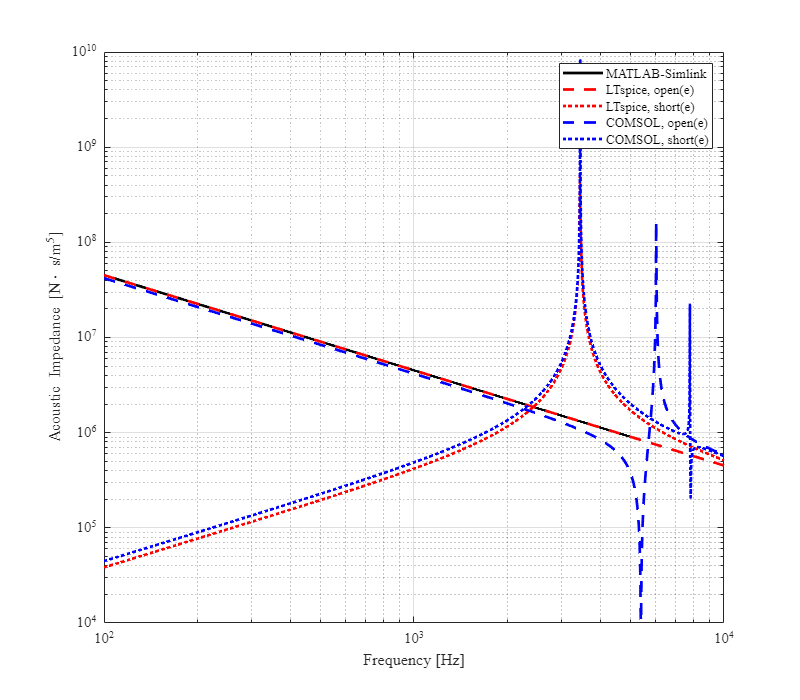

ac.co.L     = 38361.196102405345/(2*pi*100);
ac.co.C     = 1/(2*pi*100*4.518859697974938e7);

%% Specify the model name
ac.co.model = 'AC_Compressor';

%% Specify the analysis I/Os
% Get the analysis I/Os from the model
ac.co.io = getlinio(ac.co.model);

%% Specify the operating point
% Use the model initial condition
ac.co.op = operpoint(ac.co.model);

%% Linearize the model
ac.co.sys = linearize(ac.co.model,ac.co.io,ac.co.op);

w = linspace(0,2*pi*5000,5001);
freq = w/(2*pi);
[ac.co.mag, ac.co.phase] = bode(ac.co.sys,w);

ac.co.Z = squeeze(ac.co.mag)';
ac.co.argZ = squeeze(ac.co.phase)';

ac.co.LTspice = readLTspiceZ('AC -220722 - Compressor_.txt',1,801);

ac.co.COMSOL.open   = readCOMSOLZ('AC -220722 - Compressor, 2DX, open(e), abs(Z).txt',9);
ac.co.COMSOL.short  = readCOMSOLZ('AC -220722 - Compressor, 2DX, short(e), abs(Z).txt',9);

plotcompZ(freq,ac.co.Z,...
    [ac.co.LTspice.freq ac.co.LTspice.freq],[ac.co.LTspice.abs_z_o ac.co.LTspice.abs_z_s],...
    [ac.co.COMSOL.open.freq ac.co.COMSOL.short.freq], [ac.co.COMSOL.open.value ac.co.COMSOL.short.value],...
    1e2,1e4,'log');

## Mouth (plane circular piston in infinite baffle)

Need to implement 6th order radiation impedance

ac.rad.s    = Geom_Horn.Area(end);
ac.rad.a    = sqrt(ac.rad.s/pi);

ac.rad.Rm1  = 1.386*ac.rad.a^2*air.rho0*air.c;
ac.rad.Rm2  = ac.rad.s*air.rho0*air.c;
ac.rad.Cm1  = 1.89/(pi*ac.rad.a*air.rho0*air.c^2);
ac.rad.Mm1  = 8*ac.rad.a^3*air.rho0/3;

**make the impedance check of components in acoustical doamin**

SPL check ok !

% %% Specify the model name
% model = 'AC_Test';
% 
% %% Specify the analysis I/Os
% % Get the analysis I/Os from the model
% io = getlinio(model);
% 
% %% Specify the operating point
% % Use the model initial condition
% op = operpoint(model);
% 
% %% Linearize the model
% sys = linearize(model,io,op);
% 
% w = linspace(0,2*pi*5000,5001);
% [mag, phase] = bode(sys,w);
% vel = squeeze(mag)';
% freq = w/(2*pi);
% sp = vel.*freq*air.rho0/air.p_ref/sqrt(2);
% plot(freq,mag2db(sp));

# **Mechanical components**

## Diaphragm

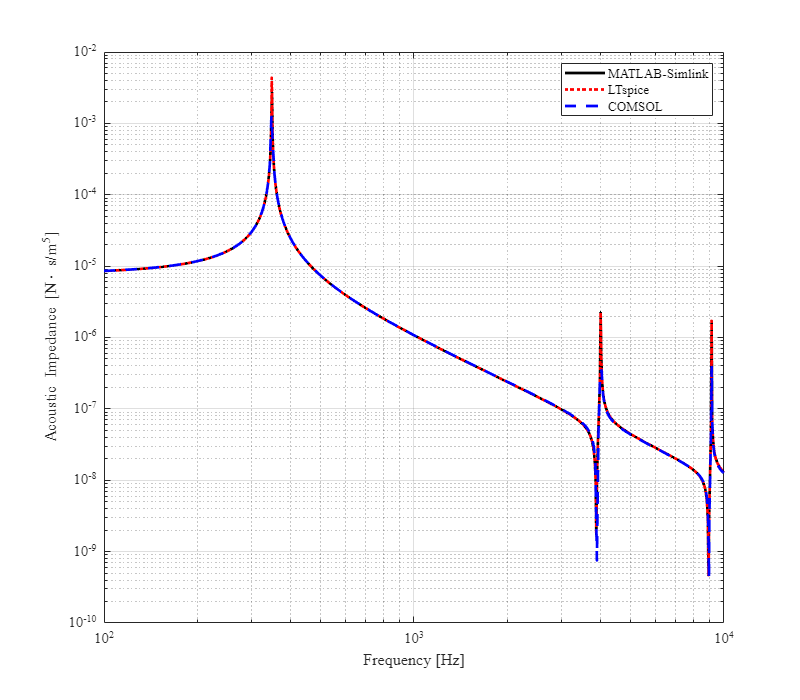


me.di.R    = 1;                     % Damping coefficient,  [N.s/m]
%% for 1DOF non-linear driver
me.dn.M    = 0.028596625123380574;  % Mass,                 [kg]
me.dn.K    = [134757.51424041812   7.399527807648116E7 1.0743542290213011E11 0 0];
                                    % Spring coefficients,  [N/m]
%% for 3DOF linear driver
me.dl.f    = [347.8491105695766 4002.8759129004957 9118.609276012086];
me.dl.phi  = [37.47048679642662 2.4855617498927827 1.8325667984395029];

%% Spring swtich from the experiment result (FD curve of spring)
me.sw.K_pt  = 31e3;                 % Pretensioned-spring coefficients, [N/m]
me.sw.K     = 7e3;                  % Spring coefficients,  [N/m]

%% Specify the model name
me.dl.model = 'ME_Diaphragm_3DOF_linear';

%% Specify the analysis I/Os
% Get the analysis I/Os from the model
io = getlinio(me.dl.model);

%% Specify the operating point
% Use the model initial condition
op = operpoint(me.dl.model);

%% Linearize the model
me.dl.sys = linearize(me.dl.model,io,op);

wlog    = 2*pi*logspace(2,4,1001);
freqlog = wlog/(2*pi);

%% Plot the resulting linearization
[me.dl.mag, me.dl.phase] = bode(me.dl.sys,wlog);

me.dl.x         = squeeze(me.dl.mag)';
me.dl.LTspice   = readLTspiceFRF('ME_Diaphragm_3DOF_linear_.txt',1,2001);
me.dl.COMSOL.r  = readCOMSOLFRF('ME_Diaphragm_3DOF_linear_COMSOL_RFRF.txt',9);

plotcompFRF(freqlog,me.dl.x,...
    [me.dl.LTspice.Freq],[me.dl.LTspice.abs_me_x],...
    [me.dl.COMSOL.r.freq], [me.dl.COMSOL.r.value],...
    1e2,1e4,'log');

# **Mechano-acoustical coupling**

## Diaphragm

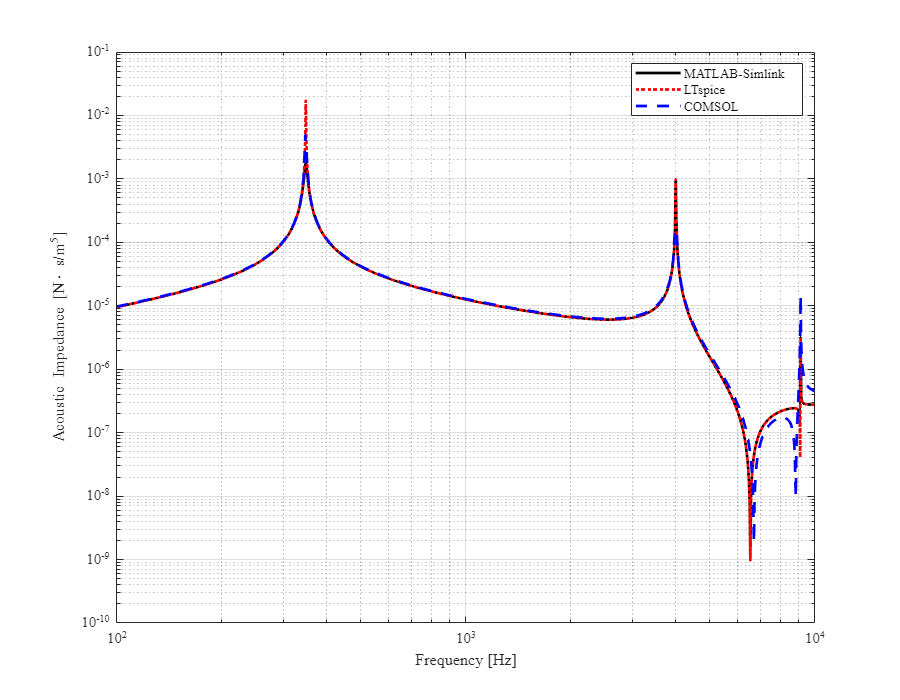

ma.di.s    = 0.0036417751495247705;
ma.di.psi  = [0.49105789017885293	4.641306076294213	0.008159872921131028];

%% Specify the model name
ma.dl.model = 'MA_Diaphragm_3DOF_linear';

%% Specify the analysis I/Os
% Get the analysis I/Os from the model
io = getlinio(ma.dl.model);

%% Specify the operating point
% Use the model initial condition
op = operpoint(ma.dl.model);

%% Linearize the model
ma.dl.sys = linearize(ma.dl.model,io,op);

%% Plot the resulting linearization
[ma.dl.mag, ma.dl.phase] = bode(ma.dl.sys,wlog);

ma.dl.x         = squeeze(ma.dl.mag)';
ma.dl.LTspice   = readLTspiceFRF('ME_Diaphragm_3DOF_linear_.txt',1,2001);
ma.dl.COMSOL.vv = readCOMSOLFRF('ME_Diaphragm_3DOF_linear_COMSOL_VVFRF.txt',9);

plotcompFRF(freqlog,ma.dl.x,...
    [ma.dl.LTspice.Freq],[ma.dl.LTspice.abs_ac_v],...
    [ma.dl.COMSOL.vv.freq], [ma.dl.COMSOL.vv.value],...
    1e2,1e4,'log');

# **Electrical components**

## Coil

el.coil.Ls  = 2e-3;         % Coil series inductance,       [H]
el.coil.Rs  = 550e-3;       % Coil series resistance,       [Ohm]

## Power Supply

el.ps.V     = 12;           % Power supply voltage,         [V]

## Switch

el.sw.R_on  = 1e-3;         % On state switch resistance,   [Ohm]
el.sw.R_off = 1e7;          % Off state switch resistance,  [Ohm]

# **Electro-mechanical coupling**

## Force factor

em.ff       = -1.45;        % negative sign for sign convention,    [N/A]

## Spring swtich

em.sw.x_on_pt   = -70e-6;   % Transition position from spring switch free to pretensioned,  [m]
em.sw.x_off     = -200e-6;  % Transition position from spring switch pretensioned to off,   [m]
em.sw.l_arc     = 50e-6;    % Arc length